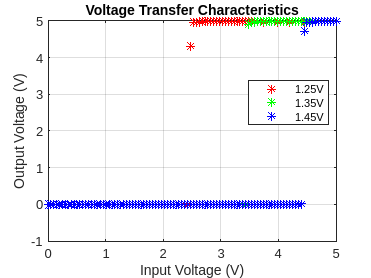

load("AkshatsEXP1Data.mat")
V125 = AK_EXP1_V1_25;
V135 = AK_EXP1_V1_35;
V145 = AK_EXP1_V1_45;
Vout25 = AK_EXP1_Vout_25;
Vout35 = AK_EXP1_Vout_35;
Vout45 = AK_EXP1_Vout_45;


% Plot VTCs
figure;
plot(V125, Vout25, 'r*', 'LineWidth', 1.5);
hold on;
plot(V135, Vout35, 'g*', 'LineWidth', 1.5);
plot(V145, Vout45, 'b*', 'LineWidth', 1.5);

% Add labels and title
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title('Voltage Transfer Characteristics');
legend('1.25V', '1.35V', '1.45V', Location='best');
grid on;
print("-depsc","experiment_1.eps")

plt1 = csvread("AK_Exp3_Plot1_Small_Amplitude.csv");

plt1 =    -0.0025    1.5917    1.5847
   -0.0025    1.5920    1.5847
   -0.0025    1.5917    1.5840
   -0.0025    1.5917    1.5843
   -0.0025    1.5910    1.5847
   -0.0025    1.5913    1.5850
   -0.0025    1.5910    1.5843
   -0.0025    1.5913    1.5843
   -0.0025    1.5913    1.5847
   -0.0025    1.5913    1.5847


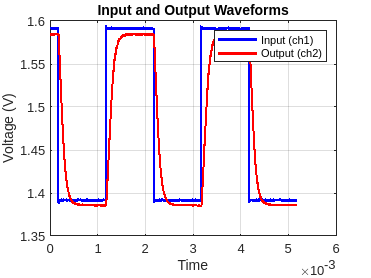

time=plt1(:,1,:);
ch1=plt1(:,2,:);
ch2=plt1(:,3,:);
time = time + 0.002480921083806;

% Plot input and output waveforms
figure;
plot(time, ch1, 'b', 'LineWidth', 2); hold on;
plot(time, ch2, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Voltage (V)');
title('Input and Output Waveforms');
legend('Input (ch1)', 'Output (ch2)');
grid on;

% 
% % Extract time constants
% % Find the time points where the output settles to its final value for both up-going and down-going transitions
% % You can use different methods for this, such as finding the time it takes for the output to reach a certain percentage of its final value
% 
% % For example, let's say you define settling as reaching 90% of the final value
% threshold = 0.88 * max(ch2);
% 
% % Find time constants for up-going transition
% up_transient = find(ch2 >= threshold, 1);
% up_time_constant = time(up_transient) - time(1);  
% 
% % Find time constants for down-going transition
% down_transient = find(ch2 <= threshold, 1);
% down_time_constant = time(down_transient) - time(1);  
% 
% fprintf('Up-going time constant: %f\n', up_time_constant);

Up-going time constant: 0.000000


% fprintf('Down-going time constant: %f\n', down_time_constant);

Down-going time constant: 0.000408


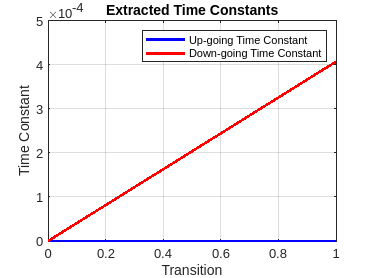

% 
% % Plot extracted time constants
% figure;
% plot([0, 1], [0, up_time_constant], 'b', 'LineWidth', 2); hold on;
% plot([0, 1], [0, down_time_constant], 'r', 'LineWidth', 2);
% xlabel('Transition');
% ylabel('Time Constant');
% title('Extracted Time Constants');
% legend('Up-going Time Constant', 'Down-going Time Constant');
% grid on;